1 - Analyse spectrale d'un signal sinusoïdal échantillonné en temps.

1.1 Synthèse d'un signal sinusoïdal échantillonné en temps.

On génère le vecteur T à partir des variables de fréquence Fe et d'échantillonnage de temps D.

clear variables;
close all;

%Initialisation des variables et du vecteur T.
D = 10;
Tech = D*10;
Fe = D/25;
T=0:Fe:Tech;

On va poser une valeur de v_0 qui nous est propre avec les paramètres imposé par le sujet.

A = 10;
phi_0 = 45;
v_0 = 0.43;

On retrouve la fonction du signal à la toute fin du document.

[t,s_t] = signalTP2(A, v_0,phi_0,Tech,Fe);

On trace maintenant les fonctions suivante avec les fonctions stem et plot!

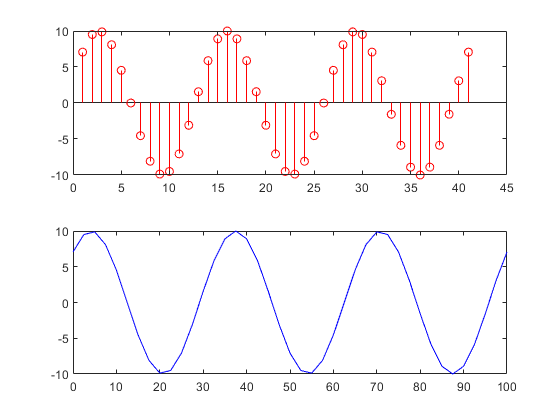

figure(1);
subplot(2,1,1);
title('Fonction stem')
stem(s_t, 'r');
subplot(2,1,2);
title('Fonction plot')
plot(t,s_t,'b');

— Expliquer pourquoi il n’y a pas eu besoin de programmer explicitement la fonction `porte` uD (t − D/2) figurant dans l’expression de s(t).

Il n'y a pas eut besoin d'expliciter la fonction porte car l'ensemble dans lequel on calcul notre fonction est l'ensemble T. Et cet ensemble est limité sur l'intervalle 0 à 10*D, ce qui correspond à l'action de notre porte sur le signal.

— Que peut-on dire du signal affiché entre deux échantillons consécutifs ?

Le signal affiché entre deux échantillons consécutif est constitué d'une ligne droite pour le plot et d'un vide pour le stem. Si l'on a beaucoup d'échantillons, ça ne posera pas de problème. Cependant, avec un échantillonnage trop faible, il est possible de ne plus obtenir la fréquence du signal avec précision.De plus, la fonction stem, qui n'a pas d'axe des ordonnés, l'impose au signal avec une progression allant de 1 en 1. Ce qui nous amène à des choses incohérente, l'axe des ordonnés allant jusqu'à 250 (la longueur de la liste T), alors que nous voulons une longueur de 100 (10*D).

— Justifier les valeurs des paramètres choisis (notamment de Fe).

v_0 a été arbitrairement fixé ) 0.43Hz. Ce qui amène une condition sur Fe. Afin de vérifier le critère de Shannon-Nyquist, il est nécessaire que Fe>2*v_0.

— Vérifier que les paramètres A, φ0 et la durée D demandés sont bien respectés ainsi que la période du signal. 

On se base sur la figure utilisant la fonction plot. On remarque par lecture graphique que l'amplitude du signal est de 10. Ainsi, on en déduit que A est bien respecté dans la fonction. On remarque ensuite que le signal est limité sur l'intervalle [0;10*D], ce qui est cohérent avec ce que nous avons demandé. Et enfin, le signal commence au niveau de sin(45°), ce qui est compatible avec ce que nous avons demandé. (On la retrouve en prenant le premier point de notre signal, en utilisant la fonction arcsin puis en reconvertissant le résultat en degré.

1.2 Infulence de la fréquence d'échantillonnage sur l'analyse spectrale

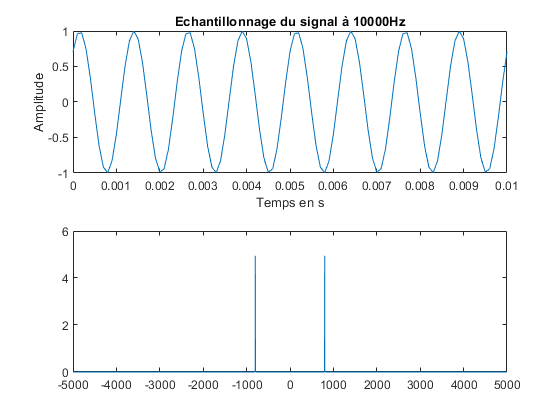

A_2 = 1;
v_2 = 800;
D_2 = 1;
Df = 10*D_2;
[t,s_t] = signalTP2(A_2, v_2,phi_0,Df,Fe);

figure(2);

Fe2 = 10000;
[t_2,s_t2] = signalTP2(A_2, v_2,phi_0,Df,Fe2);
[SignalTP,f] = TransFourier(s_t2,t_2);

subplot(2,1,1);
plot(t_2,s_t2); xlim([0,0.01]);
title('Echantillonnage du signal à 10000Hz');
xlabel('Temps en s');
ylabel('Amplitude');
subplot(2,1,2);
title('Affichage de la valeur absolue de la transformée de fourier.')
plot(f,abs(SignalTP));

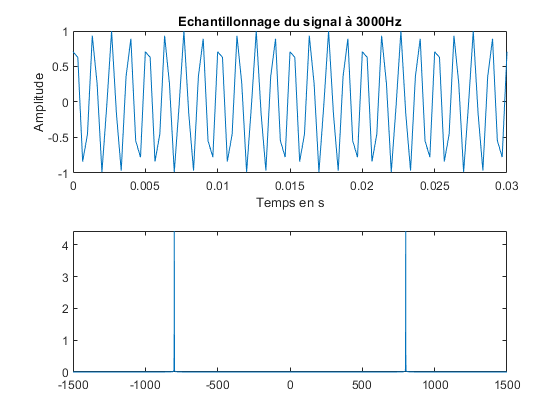


Fe2 = 3000;
[t_2,s_t2] = signalTP2(A_2, v_2,phi_0,Df,Fe2);
[SignalTP,f] = TransFourier(s_t2,t_2);

figure(3);

subplot(2,1,1);
plot(t_2,s_t2); xlim([0,0.03]);
title('Echantillonnage du signal à 3000Hz');
xlabel('Temps en s');
ylabel('Amplitude');
subplot(2,1,2);
title('Affichage de la valeur absolue de la transformée de fourier.')
plot(f,abs(SignalTP));

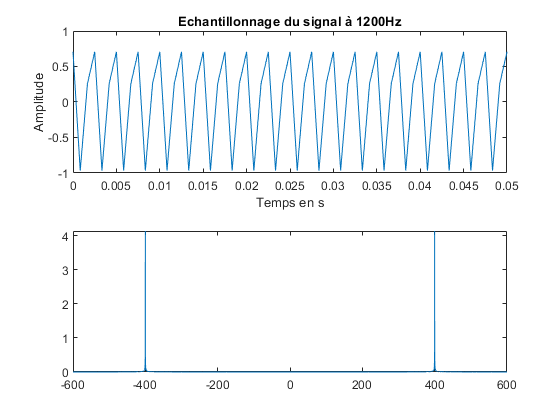


Fe2 = 1200;
[t_2,s_t2] = signalTP2(A_2, v_2,phi_0,Df,Fe2);
[SignalTP,f] = TransFourier(s_t2,t_2);

figure(4);
subplot(2,1,1);
plot(t_2,s_t2); xlim([0,0.05]);
title('Echantillonnage du signal à 1200Hz');
xlabel('Temps en s');
ylabel('Amplitude');
subplot(2,1,2);
title('Affichage de la valeur absolue de la transformée de fourier.')
plot(f,abs(SignalTP));

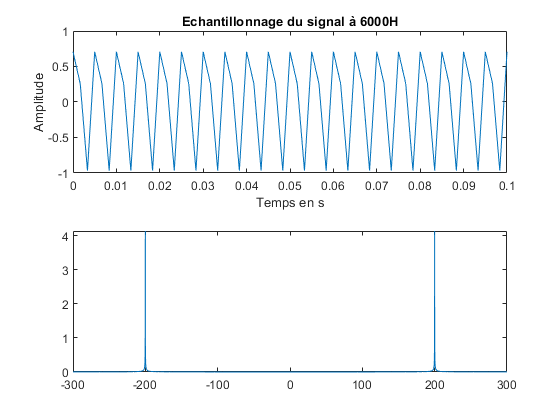


Fe2 = 600;
[t_2,s_t2] = signalTP2(A_2, v_2,phi_0,Df,Fe2);
[SignalTP,f] = TransFourier(s_t2,t_2);

figure(5);

subplot(2,1,1);
plot(t_2,s_t2);xlim([0,0.1]);
title('Echantillonnage du signal à 6000H');
xlabel('Temps en s');
ylabel('Amplitude');
subplot(2,1,2);
title('Affichage de la valeur absolue de la transformée de fourier.')
plot(f,abs(SignalTP));

On remarque que lorsque la fréquence d'échantillonage augmente, cela éloigne les pics entre eux. (Ils se situent donc à une fréquence plus élevé.)

La fondamentale se trouve toujours à 800Hz théoriquement (car il a été initialisé avec v_2 = 800Hz). Lorsqu'on a une Fe2 supérieur au critère de Shannon, la différence entre la fondamentale et Fe2+-v_2 permet d'échantillonner correctement le signal et donc de  récuperer la fondamentale à 800Hs. Cela explique que par exemple, pour Fe2= 10kHz, on observe des pics à + et - 800Hz.

Quand on est inférieur au x critère de Shannon, il y a un replis spectrale et la fréquence des pics apparaissant est alors égale à Fe2-v_2 et v_2-Fe2. Cela peut se voir pour Fe2 = 600Hz, où on observe les pics à + et - 200Hz.

2 Analyse spectrale de signaux réels

J'ai choisit pour cette seconde partie d'analyser le bruit d'un éléphant dans un premier temps.

Pour trouver la fréquence d'échantillonnage minimal pour le signal, il faut tout d'abord commencer par analyser le signal avec la plus grande fréquence possible. Ensuite, par lecture graphique, on observe la fréquence max du signal entre les deux spectre. 

Par exemple, pour une fréquence d'échantillonnage de 16 kHz, on trouve une fréquence max d'environ 3,5kHz. 

On essaie de descendre d'un cran, à 8kHz et on observe que la fréquence max est toujours présente à 3,5kHz sur le spectre en décibel. 

Cependant, une fois arrivé à 4kHz, on remarque que le spectre max est dorenavant de 2kHz, ce qui est loin des 3,5kHz précédent.

Comme la fréquence max à baisser entre 8kHz et 4kHz, on en déduit que la fréquence d'échantillonnage minimale pour le bruit d'éléphant est de 8kHz.

En reprenant le même principe pour les autres échantillons, on obtient alors : 

- Chauve souris : 400 kHz.

- Décollage d'avion : 5 kHz.

- Vibration moteur : 20 kHz.

- Echo sonar : 8 MHz.

- EEG : 250Hz

La fonction du signal de la partie 1.

function [T,s] = signalTP2(A,v_0,phi_0,D,Fe)
    T =  0:1/Fe:D;
    s =  A*sin(2*pi*v_0*T+phi_0*pi/180);
end
